# 預測性維護範例

**練習1 : 基本資料匯入與繪圖 10:00~10:10**

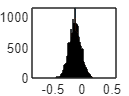

data_first = readtable('.\Vibration_data\2003.11.23.05.36.56.txt');
% 分號讓其不顯示運算結果
data_last = readtable('.\Vibration_data\2003.11.25.23.39.56.txt');

figure
histogram(data_first.Var2)
hold on %讓做出來的圖保留，疊加下一個圖
histogram(data_last.Var2)
hold off


s_first = std(data_first.Var2) %標準差

s_first = 0.0900

s_last = std(data_last.Var2)

s_last = 0.1064

**練習2 : Datastore 10:27~10:35**

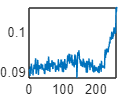

ds = fileDatastore('.\Vibration_data\', 'FileExtensions', '.txt', 'ReadFcn', @(x) readtable(x)); 
%ds = fileDatastore('.\Vibration_data\', FileExtensions='.txt', ReadFcn=@(x) readtable(x)); 功能同上
%將資料夾下檔名結尾為.txt的檔案用@(x)即readtable(x)來讀
d1 = read(ds); %讀第一個檔名(多次執行依序往下)
%D = readall(ds); 將全部檔案牘近來，要小心記憶體爆炸和檔名不符之情況
%preview(ds) 預覽資料，似head
reset(ds) %重製讀檔的順序

%{
n = length(ds.Files);
for i = 1:n
end
%}
i = 1;
while hasdata(ds) %判斷是否還有下一筆資料
    data_tmp = read(ds);
    s(i) = std(data_tmp.Var2);
    i = i + 1;
end

figure
plot(s)

**練習3 : 特徵萃取 11:22~11:35**

ds2 = fileDatastore('.\Vibration_data\', 'FileExtensions', '.txt', 'ReadFcn', @(x) readtable(x, Range="B:B")); %類似excel命名法

d = readall(ds2);

label = [repmat({'Normal'}, 241, 1); repmat({'Abnormal'}, 20, 1)]; %特徵值得標註應由專業人員判斷何為異常
label = categorical(label); %節省記憶體

Data = table(d, label)

Data = 261×2 table
           d           label 
    _______________    ______

    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal
    {20480×1 table}    Normal



%load ex2_DFD_data.mat 前面內容沒做的可以直接讀檔開始(有之前產出的結果)
%diagnosticFeatureDesigner 用指令打開
Feat = my_code_feature(Data); %將其存檔後可直接用funtion引用他，會產出相同結果

**練習4 : 機器學習**

%load ex3_classiicationLearner_featureTable.mat 前面內容沒做的可以直接讀檔開始(有之前產出的結果)
%classificationLearner 用指令打開
%yfit = trainedModel.predictFcn(T) T為待預測用data，此指令為使用trainedModel進行預測